# Phase-lead compensator to explain phase-leading behavior in *Drosophila* head movements

clear; close all; clc
syms s I c k K_p K_d K_i a_2 tau K
assume([I c k s]>=0)
assume([I c k],'real')

## Contol Framework

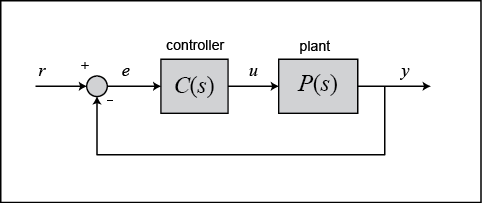

### Plant

P(s) = 1/(0.2*s + 1)

$$P(s) = \frac{1}{\frac{s}{5}+1}$$

### Controller to achieve zero steady-state error

C1(s) = K*(1/s)

$$C1(s) = \frac{K}{s}$$

### Closed-Loop Model


$$G\left(s\right)=\frac{Y\left(s\right)}{R\left(s\right)}=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)}$$


G(s) = collect(simplify(P(s)*C1(s)/(1 + P(s)*C1(s))),s)

$$G(s) = \frac{5\,K}{s^{2}+5\,s+5\,K}$$

### Error Dynamics


$$H\left(s\right)=\frac{E\left(s\right)}{R\left(s\right)}=\frac{1}{1+P\left(s\right)C\left(s\right)}$$


H(s) = collect(simplify(expand(1/(1+P(s)*C1(s)))),s)

$$H(s) = \frac{s^{2}+5\,s}{s^{2}+5\,s+5\,K}$$

#### For ramp input

$E\left(s\right)=\frac{R\left(s\right)}{1+P\left(s\right)C\left(s\right)}$    where $R\left(s\right)=\frac{1}{s^2 }$

R = 1/s^(2);

#### Steady-State Error using FVT


$$e_{\mathrm{ss}} =\underset{t\to \infty }{\mathrm{lim}} \;e\left(t\right)=\underset{s\to 0}{\mathrm{lim}} \;\mathrm{sE}\left(s\right)$$


Ess = limit(s*H(s)*R,s,0)

$$Ess = \frac{1}{K}$$

#### Neccesary Gain

K_num = solve(Ess==0.02,K)

$$K\_num = 50$$

K_num = 1;

#### The new subcomponents

C1(s) = subs(C1(s),K,K_num)

$$C1(s) = \frac{1}{s}$$

G(s) = subs(G(s),K,K_num)

$$G(s) = \frac{5}{s^{2}+5\,s+5}$$

figure (1) ; clf
margin(sym2tf(G(s))) ; hold on

## Phase-Lead Compensator Controller Design

The controller is of the form


$$C\left(s\right)=\frac{a_2 \tau s+1}{\tau s+1}$$


C2(s) = (a_2*tau*s + 1)/(tau*s + 1)

$$C2(s) = \frac{a_{2}\,s\,\tau +1}{s\,\tau +1}$$

The phase addition and  frequency peak are defined as

$\phi_{\mathrm{max}} ={\mathrm{sin}}^{-1} \left(\frac{a_2 -1}{a_2 +1}\right)$   &   $\omega_{\mathrm{max}} =\frac{1}{\tau \sqrt{a_2 }}$

wm = 22.5;
phi = deg2rad(37);
a2_num = double(solve(phi == asin((a_2-1)/(a_2+1))))

a2_num = 4.0228

tau_num = 1/(wm*sqrt(a2_num))

tau_num = 0.0222

The compensator controller becomes

C2(s) = simplify(expand(subs(C2(s),[a_2 tau],[a2_num tau_num])));

And the combined controller

C(s) = C1(s)*C2(s);

The new closed-loop model

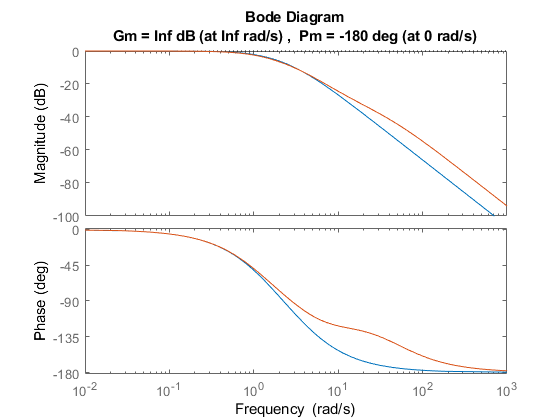

G(s) = simplify(expand(P(s)*C(s)/(1 + P(s)*C(s))));
margin(sym2tf(G(s)))

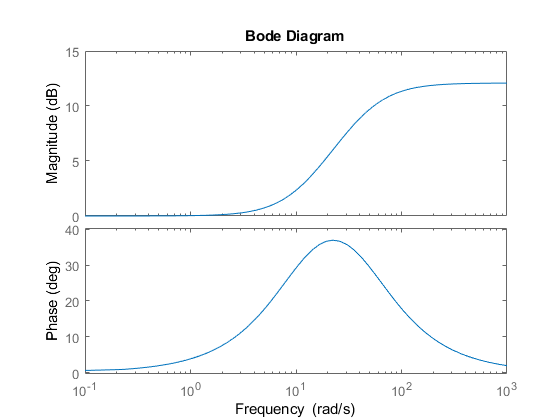


C2_num = simplify(subs(C2(s),[a_2 tau],[a2_num tau_num]));
C2_tf = sym2tf(C2_num);
bode(C2_tf)

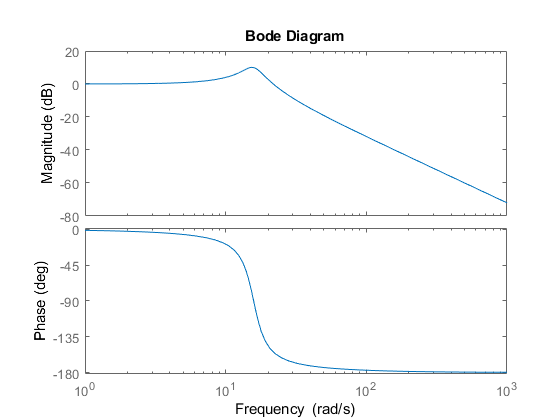

G_num = subs(G(s),[K a_2 tau],[K_num a2_num tau_num]);
bode(sym2tf(G_num))

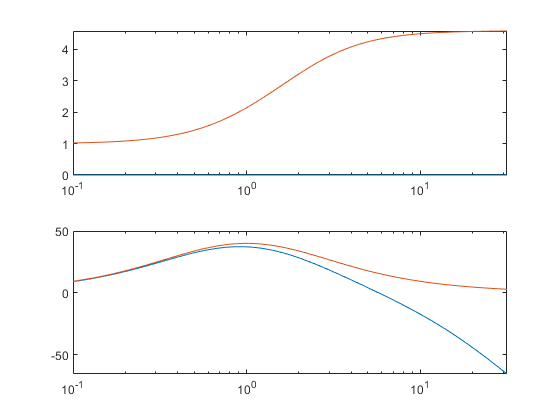

[mag,phase,freq] = bode(sym2tf(G_num),logspace(-1,2,1000));
figure (1) ; clf
ax(1) = subplot(2,1,1);
semilogx(freq,squeeze(mag)) ; hold on
% ylim([0 1])
ax(2) = subplot(2,1,2);
semilogx(freq,squeeze(phase)) ; hold on
set(ax,'XLim',10.^[-1 1.5])

[mag,phase,freq] = bode(sym2tf(C_num),logspace(-1,2,1000));
ax(1) = subplot(2,1,1);
semilogx(freq,squeeze(mag))
ax(2) = subplot(2,1,2);
semilogx(freq,squeeze(phase))
set(ax,'XLim',10.^[-1 1.5])


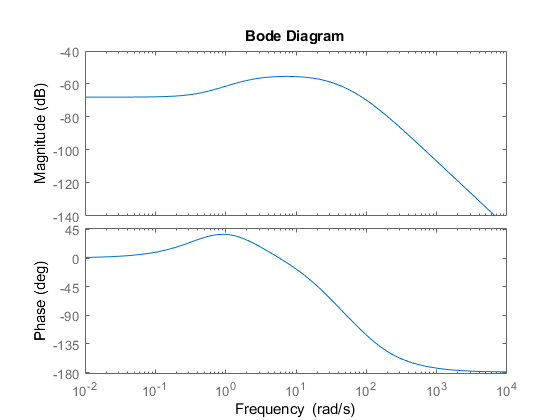

figure (2) ; clf
bode(sym2tf(G_num))